clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\18F\Data_M4STI1_2018F.xlsx");


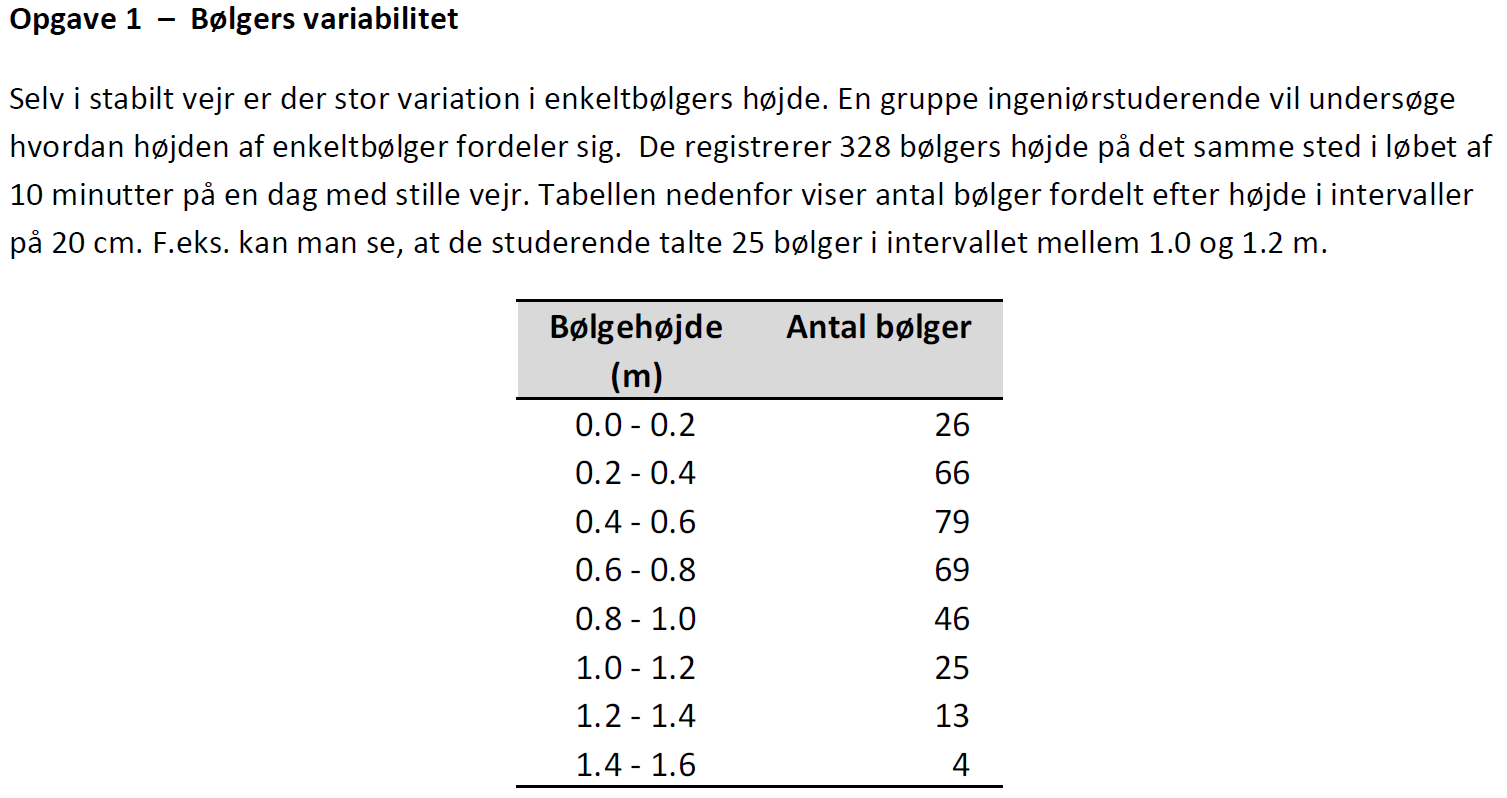

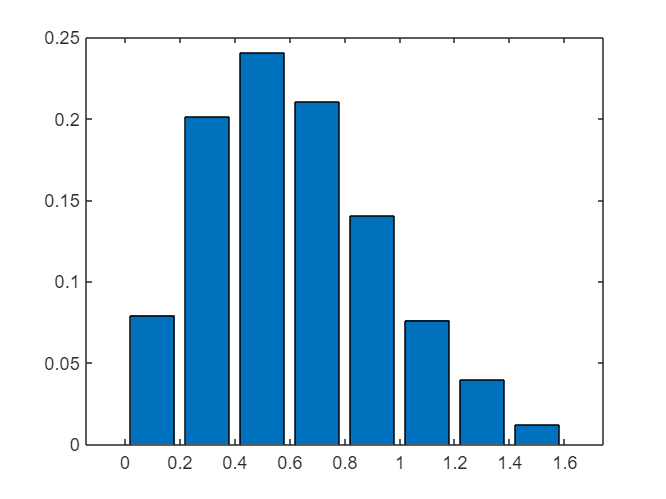

bolge_hojde_min = data(1:8, 1);
bolge_hojde_max = data(1:8, 2);
bolge_antal = data(1:8, 3);

prob = bolge_antal / sum(bolge_antal);
medium = (bolge_hojde_min + bolge_hojde_max)/2;
bar(medium, prob)

b. Beregn den kumulerede sandsynlighedsfordeling for bølgehøjden.

init = 0;
kum = [];

kum = cumsum(prob)

kum =      0.079268
      0.28049
      0.52134
      0.73171
      0.87195
      0.94817
       0.9878
            1


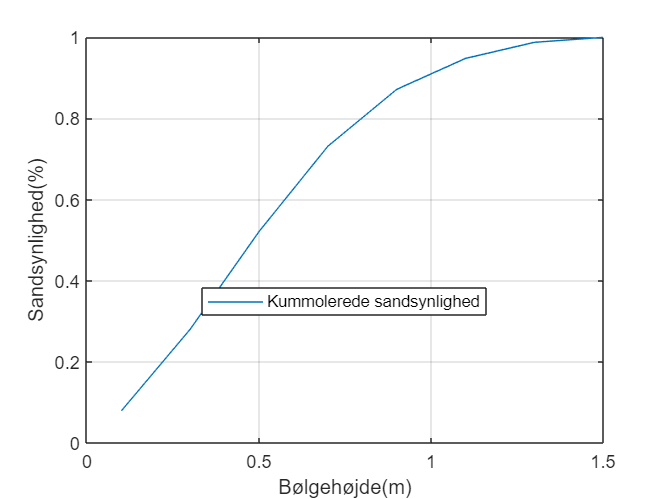

plot(medium, kum,'DisplayName', 'Kummolerede sandsynlighed')
ylabel('Sandsynlighed(%)')
xlabel('Bølgehøjde(m)')
legend('location', 'best')%, 'northeastoutside')
grid("on")

c. Hvad er sandsynligheden for at den næste bølge er højere end 1.0 m?

hoj_1m = sum(prob(6:8))

hoj_1m =       0.12805


d. Beregn den gennemsnitlige bølgehøjde (antag at alle bølgerne i et interval har samme højde, nemlig intervallets midterværdi).

N = sum(bolge_antal)%328%length(medium);

N =    328


sum(medium .* bolge_antal)/N

ans =       0.61585


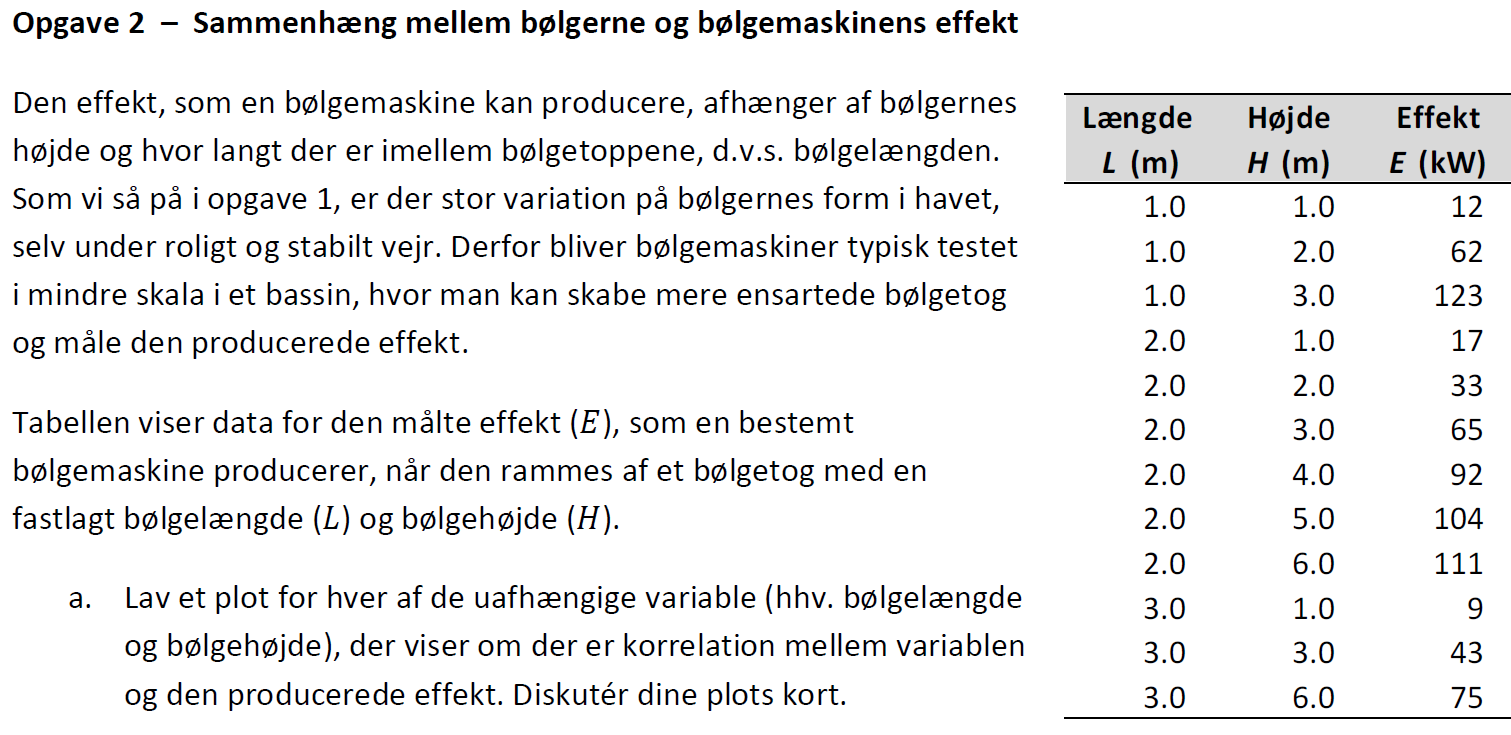

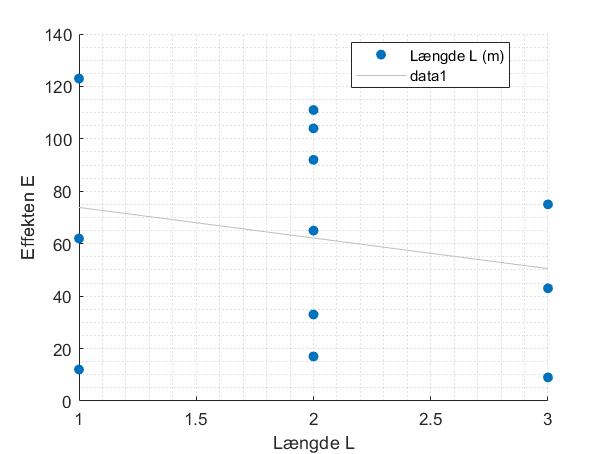

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\18F\Data_M4STI1_2018F.xlsx");

L = data(1:12, 5);
H = data(1:12, 6);
E = data(1:12, 7);


figure(1)
scatter(L, E, 'filled', DisplayName='Længde L (m)')
lsline
xlabel('Længde L')
ylabel('Effekten E')
grid('minor')
legend('Location','best')

Her ses en svag negativ koreletion, dog er der meget stor spredning på dataen og det kan således være at der ingen sammenhæng er.

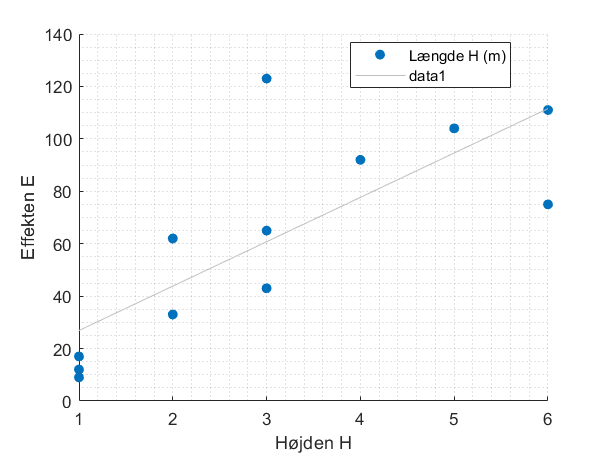

figure(2)
scatter(H, E, 'filled', DisplayName='Længde H (m)')
lsline
xlabel('Højden H')
ylabel('Effekten E')
grid('minor')
legend('Location','best')

b. Lav en multipel lineær regressionsanalyse, der beskriver produceret effekt som funktion af bølgelængde og bølgehøjde. Skriv regressionsligningen op.

mdl1 = fitlm([L, H],E) %, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2')

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)      51.19     18.113     2.8261      0.019848
    x1             -24.737     8.3794    -2.9522      0.016164
    x2              19.606     3.3781     5.8038    0.00025826


Number of observations: 12, Error degrees of freedom: 9
Root Mean Squared Error: 19.8
R-squared: 0.799,  Adjusted R-Squared: 0.754
F-statistic vs. constant model: 17.9, p-value = 0.000732


$$E(L, H) = 51,19 - 24,737 \cdot L + 19,606 \cdot H$$
 

c. Forklar v.h.a. regressionsanalysens statistikker og dine plots fra delopgave a., om modellen beskriver observationerne godt.

Modellen beskriver observationerne mindre godt, dette ses på den lave R værdi som helst, det ser ud til at det på scatter plot fra længden i opgave a kan være problemet. Dog ser p-værdierne ud til være fine ift. significans nivue på 5%.

d. Undersøg om der er ’unormale’ datapunkter, d.v.s. outliers, løftestangs- eller indflydelses-punkter.

lev = mdl1.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen
rst = mdl1.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3

c = 2; %antal regressor variable
n = length(rst) %antalt observationer

n =     12


lev_limit = 2 * (c +1 )/ n

lev_limit =           0.5


find(lev > lev_limit)


ans =

  0×1 empty double column vector



find(abs(rst) > 3)

ans =      3


nr = (1:length(rst))';
disp(table(nr, L, H, E, lev, rst))

    nr    L    H     E       lev         rst   
    __    _    _    ___    ________    ________

     1    1    1     12      0.3086     -2.7008
     2    1    2     62     0.25507    -0.20298
     3    1    3    123     0.25994      3.1069
     4    2    1     17     0.21006    -0.23264
     5    2    2     33      0.1176    -0.40657
     6    2    3     65    0.083536     0.22322
     7    2    4     92     0.10787     0.61277
     8    2    5    104     0.19059     0.22629
     9    2    6    111     0.33171    -0.49451
    10    3    1      9      0.4708     0.84989
    11    3    3     43     0.26642     0.40523
    12    3    6     75     0.39781     -1.3323



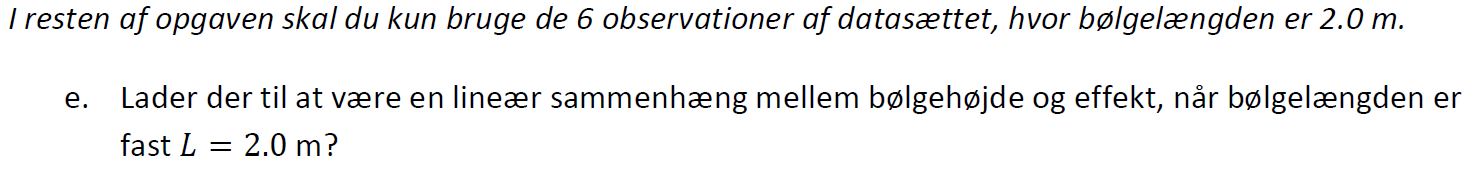

L = data(4:9, 5);
H = data(4:9, 6)

H =      1
     2
     3
     4
     5
     6


E = data(4:9, 7);
mdl2 = fitlm([H],E) %, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2')

mdl2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    ______    _________    __________

    (Intercept)    -0.66667    8.3514    -0.079827       0.94021
    x1               20.286    2.1444       9.4597    0.00069657


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 8.97
R-squared: 0.957,  Adjusted R-Squared: 0.947
F-statistic vs. constant model: 89.5, p-value = 0.000697

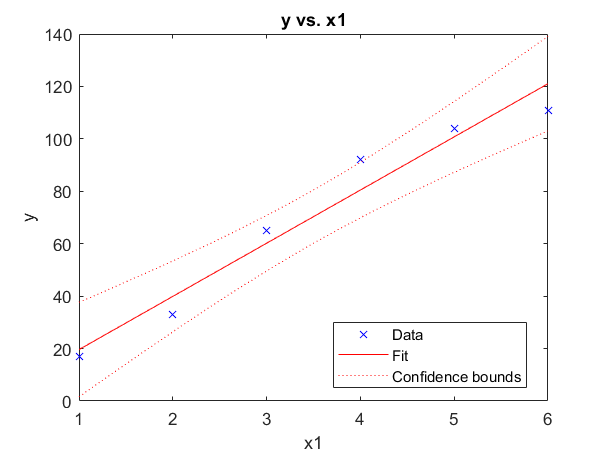

plot(mdl2)

Vi får nu en meget bedre R - værdi, dog er p værdien for skærings punktet(intercept) er meget dårlig(0,94).

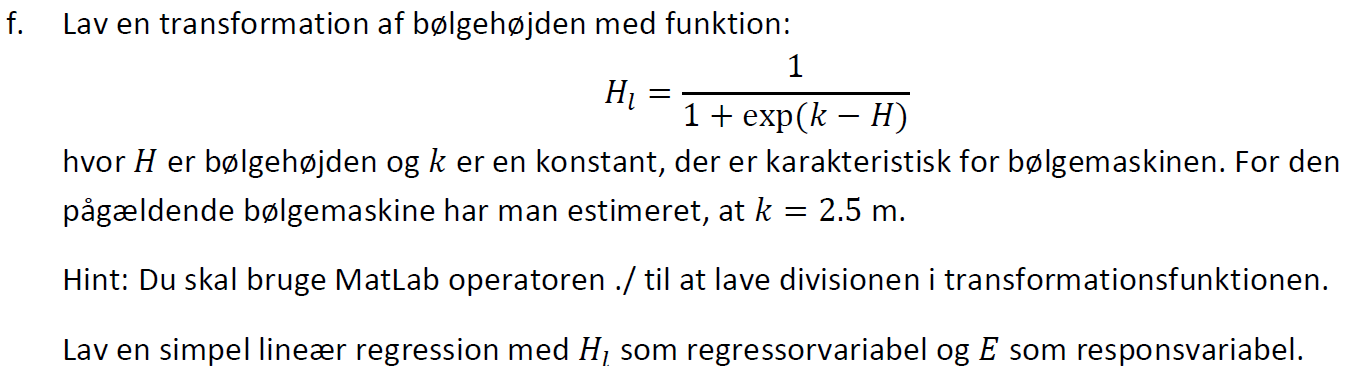

k = 2.5;



H_l = 1 ./ (1 + exp(k - H))

H_l =       0.18243
      0.37754
      0.62246
      0.81757
      0.92414
      0.97069


mdl3 = fitlm([H_l],E)

mdl3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -9.1154     3.1056    -2.9351      0.042597
    x1              122.39     4.3717     27.996    9.6844e-06


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 3.09
R-squared: 0.995,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 784, p-value = 9.68e-06

E_H = @(x) -9.1154 + 122.39 * 1 / (1 + exp(k - x));

E_H = function_handle with value:
    @(x)-9.1154+122.39*1/(1+exp(k-x))



E_H(4.7)

ans =        101.07


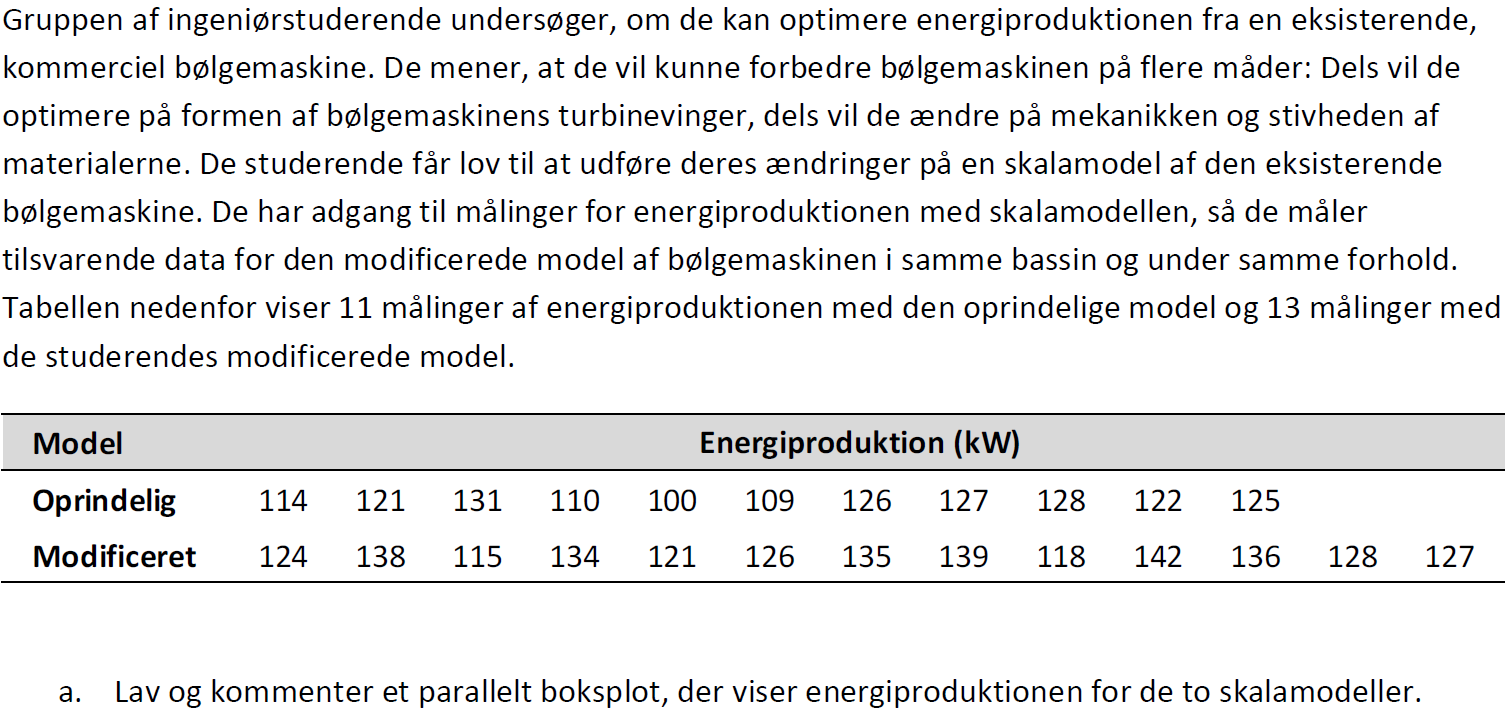

clear all
clf

data = xlsread("Eksamens sæt\18F\Data_M4STI1_2018F.xlsx", ("I:J"));

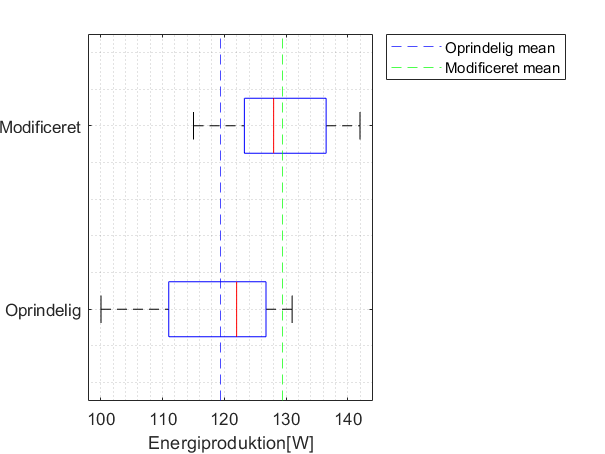



% oprindelig = data(1:11,1)
% modificeret = data(12:11+13,2)
type = data(:, 1);
energi = data(:, 2);

boxplot(energi, type, 'Orientation','horizontal', ...
     "Labels", {'Oprindelig', 'Modificeret'})
xline(mean(data(1:11,2)), '--b', 'DisplayName', 'Oprindelig mean')
xline(mean(data(12:11+13,2)), '--g', 'DisplayName', 'Modificeret mean')
xlabel('Energiproduktion[W]')
legend('location', 'northeastoutside')
grid("minor")

Den oprindelige data ser ud til at være lidt venstre skæv med en lidt længere kost. I den modificeret er der bedre sammenhæng imellem koste i plottet.

b. Man ønsker at slå fast med et signifikansniveau på 5 %, om energiproduktionen er højere med den modificerede model end med den oprindelige. Opstil nulhypotese og alternativhypotese for denne hypotesetest.


$$H_0:\ \mu_{op} - \mu_{mod}  = 0 \\
H_a:\ \mu_{op} - \mu_{mod}  < 0 $$


c. Opstil formlen for teststatistikken og beregn dens værdi. Angiv hvilken fordeling den følger.

Den følger en 1. sidet t fordeling  da populationens spredning er ukendt.

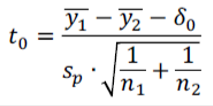

alpha = 0.05;

oprindelig = energi(1:11);
modificeret = energi(12:11+13);
n_op = length(oprindelig)

n_op =     11


n_mod = length(modificeret)

n_mod =     13


df = n_op + n_mod - 2

df =     22



y_bar_op = mean(oprindelig)

y_bar_op =        119.36


s_op = std(oprindelig)

s_op =        9.7598


var_op = var(oprindelig)

var_op =        95.255



y_bar_mod = mean(modificeret)

y_bar_mod =        129.46


s_mod = std(modificeret)

s_mod =          8.55


var_mod = var(modificeret)

var_mod =        73.103



delta_0 = 0 % y_bar_mod - y_bar_op

delta_0 =      0



% Den puljede varians var_p er et vægtet gennemsnit af de to stikprøvers varianser:
s_p = sqrt( ( (n_op -1) * s_op^2 + (n_mod -1) * s_mod^2 ) / (n_op + n_mod - 2) )

s_p =        9.1198



%test størrelsen findes
t_0 = (y_bar_op - y_bar_mod - delta_0) / (s_p * sqrt(1/n_op + 1/n_mod))

t_0 =       -2.7028


[h, p ,ci, stats] = ttest2(oprindelig, modificeret, "Alpha", alpha, "Tail", "left")

h =      1


p =     0.0064991


ci =          -Inf
      -3.6824


stats = struct with fields:
    tstat: -2.7028
       df: 22
       sd: 9.1198


d. Beregn den kritiske region for testen og konkludér på hypotesetesten.

t_c = tinv(alpha, df)

t_c =       -1.7171


e. Beregn et 95 % konfidensinterval for forskellen på materialernes middelværdi.

B = tinv(1 - alpha/2, df) * s_p * sqrt(1/n_op + 1/n_mod)

B =        7.7483



y_low = (y_bar_op - y_bar_mod) - B;

y_high = (y_bar_op - y_bar_mod) + B;
[y_low, y_high]

ans =       -17.846      -2.3496


f. Diskutter hvordan boksplot, hypotesetest og konfidensinterval stemmer overens.

De viser alle at den modificerede middelværdi ligger højere end den oprindelige models middelværdi.

for løsnings forslaget

Boksplot, hypotesetest og konfidensinterval giver det samme billede: Som nævnt under delopgave a) viser boksplottet, at der generelt er højere energiproduktion for den forbedrede bølgemaskine-model. Medianen ligger højere. Hypotesetesten i delopgave b) til d) viser, at der er signifikant forskel på middelværdierne, så den forbedrede model faktisk er en forbedring. 95% konfidenstintervallet for forskellen af middelværdier i delopgave e) indeholder ikke 0, så det understøtter, at middelværdien er størst for den forbedrede model.

g. Oplys hvilke antagelser, der er gjort i hypotesetesten, og om antagelserne er rimelige på baggrund af data.

Det antages at centralegrænseværdisætning gælder og at dataene kommer fra et "pænt" sæt.